# Tina Höflich, Christian  Lange

## Fahrzeugdaten laden

FzgDaten;

FzgDaten geladen


## 9.1 Längsdynamik

### 9.1.1 Simulation Bremsvorgang

Daten setzen:

ax_1 = -1;
ax_2 = -9;
T0 = 0.5;
T1 = 0.2;
T2 = 0.2;

Bremsvorgang simulieren

model = 'Bremsvorgang';
load_system(model)
simIn = Simulink.SimulationInput(model);
simIn = setModelParameter(simIn,...
    'SolverType','Fixed-step',...
    'FixedStep','0.01');
repeating_sequence = [0 T0 T0+T1 T0+T1+T2 20];
repeating_sequence_out = [0 0 ax_1 ax_2 ax_2];

out = sim(simIn);

Daten auslesen

outputs = out.yout;
t = out.tout;
s = outputs{1}.Values.Data;
v = outputs{2}.Values.Data;
a = outputs{3}.Values.Data;

Beschleunigung darstellen

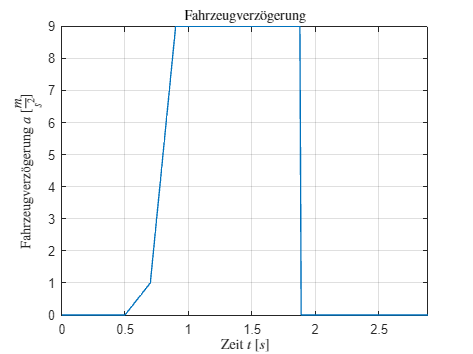

plot(t,-a)
xlabel("Zeit $t$ $[s]$", 'Interpreter','latex')
ylabel('Fahrzeugverz\"ogerung $a$ $[\frac{m}{s^2}]$','Interpreter','latex')
title ('Fahrzeugverz\"ogerung', 'Interpreter','latex');

ylim([min(-a), max(-a)])
xlim([min(t), max(t)])
grid on

Geschwindigkeit über die Zeit darstellen 

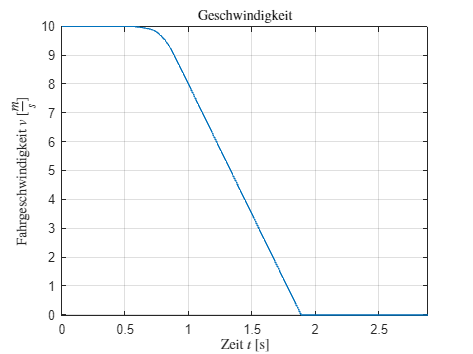

plot(t,v)
xlabel("Zeit $t$ [s]", 'Interpreter','latex')
ylabel("Fahrgeschwindigkeit $v$ $[\frac{m}{s}]$", 'Interpreter','latex')
title ('Geschwindigkeit', 'Interpreter','latex');
ylim([min(v), max(v)])
xlim([min(t), max(t)])
grid on

Strecke über die Zeitdarstellen

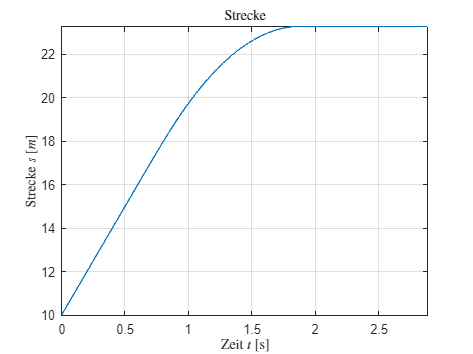

plot(t,s)
xlabel("Zeit $t$ [s]", 'Interpreter','latex')
ylabel("Strecke $s$ $[m]$", 'Interpreter','latex')
title ('Strecke', 'Interpreter','latex');
ylim([min(s), max(s)])
xlim([min(t), max(t)])
grid on

### 9.1.2 Tangentialkraftdiagramm

Das Tangentialkraftdiagramm wird in dem Simulink-Modell "Tangentialkraftverteilung" berechnet. 

clf;

model = 'Tangentialkraftverteilung';
load_system(model);
simIn = Simulink.SimulationInput(model);
simIn = setModelParameter(simIn,...
    'SolverType','Fixed-step',...
    'FixedStep','0.01');
out = sim(simIn);

Laden der Outputs des Simulink Models: 

outputs = out.yout;
psi = outputs{1}.Values.Data;
chi = outputs{2}.Values.Data;
FBh = outputs{3}.Values.Data;
FBv = outputs{4}.Values.Data;


Berechnen der Linien konstanter Abbremsung: 

Ay = -(1-psi)/chi;
Bx = psi/chi;
figure;
hold on;
for z = 0:0.2:1.0
    x = linspace(0, z);
    y = -1 * x + z;
    line(x, y, 'Color', 'r')
end


Berechnen der Charakteristische Linienscharen der Reibungszahlen:

for my = 0.6:0.2:1.0
    z = my;
    x = my * (1-psi + z * chi);
    y = my * (psi - z*chi);

    line([0 x], [Ay, y], 'Color','g')
    line([x Bx], [y, 0],'Color', 'g')
end


Plotten der Linie einer Installierten Festabstimmung: 

plot(FBv, FBh,'b');


 Hinzufügen der Beschriftungen:

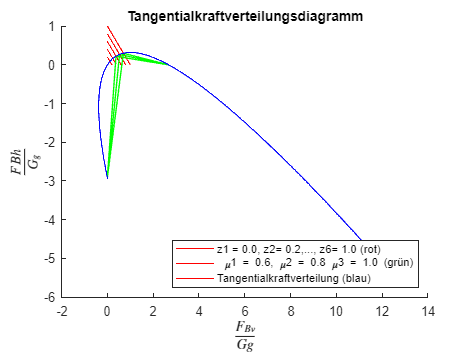


title('Tangentialkraftverteilungsdiagramm');
legend({'z1 = 0.0, z2= 0.2,..., z6= 1.0 (rot)', ...
       ' \mu1 = 0.6, \mu2 = 0.8 \mu3 = 1.0 (grün)', ...
       'Tangentialkraftverteilung (blau)'},Location="southeast")
xlabel('$\frac{F_{Bv}}{Gg}$','Interpreter','latex');
ylabel('$\frac{F{Bh}}{G_g}$','Interpreter','latex');

## 9.2 Querdynamik

### 9.2.1 Lineare Übertragungsfunktion

Ch_stern  = Ch / Fnh

Ch_stern = 20.5518

Cv_stern = Cv / Fnv

Cv_stern = 9.4854

Berechnung des Eigenlenkgradient EG

EG = (1/g) * (1/Cv_stern - 1/ Ch_stern)

EG = 0.0058

Berechnung des Schwimmwinkelgradient SG

SG = 1 / (g * Ch_stern)

SG = 0.0050

Umrechnung in m/s

v = 60 / 3.6 

v = 16.6667

Berechnung der Zählerzeitkonstante

Tz = v * SG

Tz = 0.0827

Berechnung der Abklingkonstante  $2\sigma$

abklingkonstante = (m * (Cv * Lv^2 + Ch * Lh^2) + J * (Cv + Ch)) / (J * m * v)

abklingkonstante = 18.4268

sigma = abklingkonstante / 2

sigma = 9.2134

Berechnung der ungedämpfte Eigenfrequenz $\omega^2_0$

Eigenfrequenz = (m*v^2*(Ch * Lh - Cv * Lv) + Cv * Ch * L^2)/ (J  * m * v^2)

Eigenfrequenz = 115.1613

omega_0 = sqrt(Eigenfrequenz)

omega_0 = 10.7313

Berechnung der stationäre Gierverstärkung $\frac{K}{\omega^2_0}$


gierverstaerkung = (Cv * Ch * L) / (J * m * v * Eigenfrequenz)

gierverstaerkung = 3.7815

Berechnung des Dämpfungsmaß

daempfungsmass = sigma / omega_0

daempfungsmass = 0.8586

#### Plot über die Geschwindigkeit

Formeln neu berechnen mit fortlaufender Geschwindigkeit 

v_kmh = linspace(0,250,251);
v = v_kmh ./ 3.6;
Tz_v = v .* SG

Tz_v =          0    0.0014    0.0028    0.0041    0.0055    0.0069    0.0083    0.0096    0.0110    0.0124    0.0138    0.0152    0.0165    0.0179    0.0193    0.0207    0.0220    0.0234    0.0248    0.0262    0.0276    0.0289    0.0303    0.0317    0.0331    0.0344    0.0358    0.0372    0.0386    0.0400    0.0413    0.0427    0.0441    0.0455    0.0468    0.0482    0.0496    0.0510    0.0524    0.0537    0.0551    0.0565    0.0579    0.0592    0.0606    0.0620    0.0634    0.0648    0.0661    0.0675


abklingkonstante_v = (m * (Cv * Lv * Lv + Ch * Lh.^2) + J * (Cv + Ch)) ./ (J * m * v); 
sigma_v = abklingkonstante_v / 2;
Eigenfrequenz_v = (m .* v.^2 *(Ch * Lh - Cv * Lv) + Cv * Ch * L^2) ./ (J  * m .* v.^2);
gierverstaerkung = (Cv * Ch * L) ./ ( J .* m .* v .* Eigenfrequenz_v); % K/w_0^2)
omega_0 = sqrt(Eigenfrequenz_v);
daempfungsmass = sigma_v ./ omega_0;

Berechnung der ungedämpfte Eigenfrequenz mit fortlaufender Geschwindigkeit

v_0 = omega_0 / (2 * pi); % ni0

Berechnung der gedämpfte Eigenfrequenz mit fortlaufender Geschwindigkeit

v_g = v_0 .* sqrt(1-(daempfungsmass.^2)); %ni_ret

#### Plot der ungedämpften Eigenfrequenz 

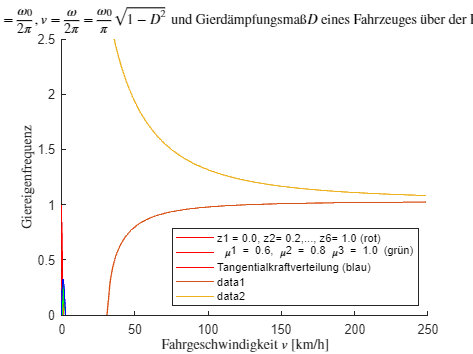

xindex = find(real(v_g) > 0);

plot(real(v_kmh(xindex-1:250)), real(v_g(xindex-1:250)));
hold on 
plot(real(v_kmh(xindex-1:250)), real(v_0(xindex-1:250))) ;
xlim([0 250]); 
ylim([0 2.5]); 
ylabel("Giereigenfrequenz", "Interpreter", "latex") 
xlabel("Fahrgeschwindigkeit $v$ [km/h]", "Interpreter", "latex") 
title (['Giereigenfreq. $v_0 = \frac{\omega_0}{2\pi}, v = \frac{\omega}{2\pi} = \frac{\omega_0}{\pi}\sqrt{1-D^2}$' ... 
    ' und Gierd\"ampfungsma\ss $D$ eines Fahrzeuges \"uber der Fahrgeschwindigkeit'] , 'Interpreter','latex') 
hold off 

#### Plot des Gierdämpfungsmaß :

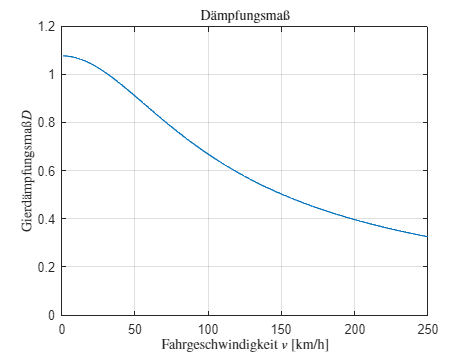


figure
plot(v_kmh, daempfungsmass)
xlim([0 250]);
title('D\"ampfungsma\ss', 'Interpreter','latex') ;

xlabel("Fahrgeschwindigkeit $v$ [km/h]", "Interpreter", "latex");
ylabel('Gierd\"ampfungsma\ss $D$', "Interpreter", "latex");
ylim([0 1.2]);
grid

### 9.2.2 Lenkradwinkelsprung  

#### Sprungantwort: von G(s)= 𝜓(𝑠)/ 𝛿(𝑠) 

unter Verwendung der Parameter

Berechnung von $G(s) = \frac{\dot{\psi}(s)}{\delta(s)} = K \cdot \frac{1 + T_zs}{s^2+2\sigma s + \omega_0^2}$

v = 60 / 3.6;
Tz = v * SG;
K = (Ch * Cv * L) / (J * m * v);

tf_gs = tf([ K*Tz K ] , [1  abklingkonstante Eigenfrequenz]);

Visaualisierung des Bode DIagramm von G(S)

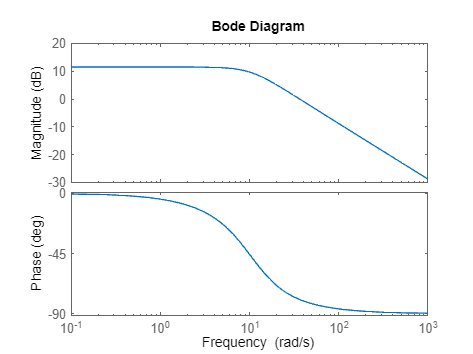

bode(tf_gs)

Berechnung der Sprungantwort :

config = RespConfig('Amplitude', 45/iS);
[y_out, t_out] = step(tf_gs, 1.0, config);
figure; % Create a new figure
plot(t_out, y_out); % Plot the step response
title('Sprungantwort', 'Interpreter','latex') ;
xlabel("Zeit $t$ [s]", "Interpreter", "latex");
ylabel(" Sprungantwort von G(s)", "Interpreter", "latex");

% Show grid
grid on;

#### Nichtlineares Einspurmodell  

model = 'Lenkradwinkelsprung';
load_system(model)
simIn = Simulink.SimulationInput(model);

*Hinweis: Alle Modellparameter, die mit *setModelParameter() *gesetzt werden können, lassen sich folgendermaßen ermitteln:*

Konfiguration der Simulation: $t_\text{Start}=0$, $t_\text{Stop}=t_{\rm end}$, Integration mit fester Zeitschrittweite $\Delta t=0.01$  

tend = 1;
simIn = setModelParameter(simIn,...
    'SolverType','Fixed-step',...
    'FixedStep','0.01',...
    'StartTime','0',...
    'StopTime',num2str(tend));

Konfiguration des Lenkradwinkelsprungs mit $\delta_\text{H}=45\degree $ und $v=60\text{ km/h}$

dH = 45;
v = 60;
simIn = setBlockParameter(simIn,"Lenkradwinkelsprung/dH","Time",'0');         % Sprung bei t=0
simIn = setBlockParameter(simIn,"Lenkradwinkelsprung/dH","After",string(dH)); % Sprunghöhe in Grad
simIn = setBlockParameter(simIn,"Lenkradwinkelsprung/v","Value",string(v));   % Konstante Geschwindigkeit in km/h

Konfiguration der Pacejka-Blöcke mit den Schräglaufsteifikgeiten $C_\text v$, $C_\text h$ und den Achslasten $F_\text{nv}$, $F_\text{nh}$

simIn = setBlockParameter(simIn,"Lenkradwinkelsprung/Einspurmodell/Reifenkräfte/Cv", "Value",string(Cv));
simIn = setBlockParameter(simIn,"Lenkradwinkelsprung/Einspurmodell/Reifenkräfte/Ch", "Value",string(Ch));
simIn = setBlockParameter(simIn,"Lenkradwinkelsprung/Einspurmodell/Reifenkräfte/Fnv","Value",string(Fnv));
simIn = setBlockParameter(simIn,"Lenkradwinkelsprung/Einspurmodell/Reifenkräfte/Fnh","Value",string(Fnh));
applyToModel(simIn) % nicht unbedingt notwendig

Lenkradwinkelsprung simulieren

out = sim(simIn);

Daten auslesen

outputs = out.yout;
outputPsip = getElement(outputs,'psip');
t    = outputPsip.Values.Time;
psip = outputPsip.Values.Data;

Darstellung der Giergeschwindigkeit $\dot\psi$ über $t$ des nichtlinearen und des linearen Einspurmodells 

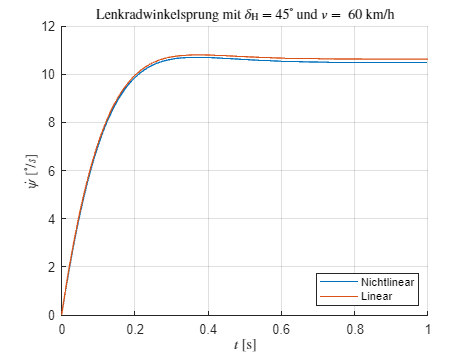

figure
hold on
plot(t,psip)
plot(t_out, y_out)
xlabel('$t$ [s]','Interpreter','latex');
ylabel('$\dot{\psi}$ $[^\circ/s]$','interpreter','latex')
title (['Lenkradwinkelsprung mit $\delta_{\rm H} = $' num2str(dH) '$^\circ$ und $v =$ ' num2str(v) ' km/h'] , 'Interpreter','latex'  )
legend('Nichtlinear','Linear','Location','southeast')
grid
hold off

### 9.2.3 Seitenkräfte

Die Kreisfahrtests sollen zusätzlich zum gegebenen Einspurmodell auch mit einem neutral steuernden sowie einem übersteuernden Einspurmodell simuliert werden.

$C_v^*$ und $C_h^*$ wurden oben schon berechnet

#### Neutral steuerndes Einspurmodell

EG = 0 mit $C_{h,0 }= C_h$


$$C_{h,0} = F_{nh} * {C_h}^* = F_{nh} * \frac{1}{\frac{F_{nv}}{C_v} - g * 0} = F_{nh} * \frac{1}{\frac{F_{nv}}{C_v}} = F_{nh} * \frac{C_v}{F_{nv}}$$


Ch_0 = Fnh * (Cv/Fnv )

Ch_0 = 6.9231e+04

#### Übersteuerndes Einspurmodell

Es gilt $EG<0$. Für die Schräglaufsteifigkeit $C_{h,i}$ gilt damit mit $C_{h,i }= C_h$

$C_{h,i} = F_{nh} * \frac{1}{\frac{F_{nv}}{C_v} - g *EG}$ und $C_{h,i} = B_h * F_{nh} * C * D$ mit $B_h \in [4...12]$

Es wird folgendes berechnet:

Zuerst Gleichung (2) in Gleichung (1) einsetzen: 


$$$B_h * F{nh} * C * D = F{nh} * \frac{1}{\frac{F{nv}}{Cv} - g EG}$$$


Da $$F_{nh}$ $auf beiden Seiten der Gleichung erscheint, kann man diese streichen, solange sie nicht null ist. Dadurch erhalten wir:


$$$B_h *C * D = \frac{1}{\frac{F{nv}}{Cv} - g EG}$$$


Um $$EG$$ zu isolieren, invertieren wir beide Seiten der Gleichung:


$$$\frac{1}{B_h * C * D} = \frac{F{nv}}{Cv} - g EG$$$


Nun können wir EG auf der rechten Seite isolieren, indem wir $$\frac{F{nv}}{Cv}$ $auf beiden Seiten der Gleichung subtrahieren:


$$$\frac{1}{B_h * C * D} - \frac{F{nv}}{Cv} = - g EG$$$


Da die rechte Seite der Gleichung negativ ist, multiplizieren wir beide Seiten der Gleichung mit -1, um EG positiv zu machen:


$$$\frac{F_{nv}}{Cv} - \frac{1}{B_h * C * D} = g EG$$$


Schließlich teilen wir beide Seiten der Gleichung durch $$g$$ um EG zu isolieren:


$$$EG = \frac{\frac{F_{nv}}{Cv} - \frac{1}{B_h* C * D}}{g}$$$


Da EG möglichst weit im Negativ liegen soll und $B_h \in [4...12]$ gilt wird $B_h = 4$ gesetzt:

EG_klein = ((Fnv / Cv) - 1 / (4 * C * D)) / g

EG_klein = -0.0027

Damit kann man $C_{h,i}$ berechnen: 

Ch_klein = Fnh * (1 / (Fnv / Cv - g * EG_klein))

Ch_klein = 5.5470e+04

#### Darstellung der Seitenkräfte

Die Seitenkräfte werden in einem Diagramm dargestellt. Hierfür wird die Pacejka-Magic-Formula: $$F_s = F_nD \sin(C\arctan(B\alpha - E(B\alpha - \arctan(B\alpha))))$
$

1. Erzeuge 100 gleichmäßig verteilte Werte zwischen 0 un 20 

alpha = linspace(0,20,200);

2. Konvertieren in Bogenmaß

alpha_bogenmass = alpha * pi / 180;

3. Verwenden der Pacejka-Funktion des Simulink Modells *Lenkradwinkelsprung *mithilfe des Skripts *Pacejka.m*

Fs_v = Pacejka(alpha_bogenmass, Fnv, Cv, C, D, E);
Fs_h = Pacejka(alpha_bogenmass, Fnh, Ch, C, D, E);
Fs_h_0 = Pacejka(alpha_bogenmass, Fnh, Ch_0, C, D, E);
Fs_h_i = Pacejka(alpha_bogenmass, Fnh, Ch_i, C, D, E);

4. Visualisieren der Seitenkräfte über den Schräglaufwinkel

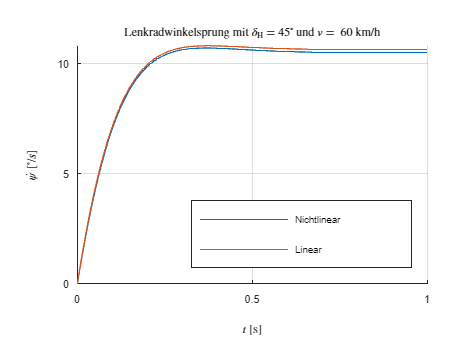

figure
hold on
plot(alpha, Fs_v, "DisplayName", "C_v")
plot(alpha, Fs_h, "DisplayName", "C_h")
plot(alpha, Fs_h_0, "DisplayName", "C_{h,0}")
plot(alpha, Fs_h_i, "DisplayName", "C_{h,i}")
xlabel('Schraeglaufwinkel $\alpha$ $[^\circ]$', 'Interpreter', 'latex')
ylabel('Seitenkr\"afte $F_s$ $[N]$', 'Interpreter', 'latex')
title('Seitenkr\"afte', 'Interpreter', 'latex')
legend('show', 'Location', 'southeast')
grid
hold off

### 9.2.4 Gesteuerte stationäre Kreisfahrt

Simulation des Manövers *Kreisfahrtest mit konstanter Geschwindigkeit  *mit  $v=60 km/h $ und $\dot\delta_H = 1\frac{\degree }{s}$

Das setzen der Parameter ist in die Funktion *gesteuerte_kreisfahrt.m* ausgelagert. 

Darin wird für alle drei Fälle die folgende Formel verwendet:


$$\delta_{H,lin} = a_y * (\frac{l}{v^2} + EG) * i_S * \frac{180^\circ}{\pi}$$


Umrechnen der Geschwindigkeit in $\frac ms$

v = 60 / 3.6;

#### *Modell 1: EG = 0*

Schräglauftsteifigkeit $C_{h,0}$ aus *Neutral steuerndes Einspurmodell *setzen, sowie die anderen Parameter und $EG = 0$

EG_0 = 0;
figure
gesteuerte_kreisfahrt(EG_0, Cv, Ch_0, Fnv, Fnh, L, iS, '#9a32cd');

#### *Modell 2: EG < 0*

Schräglauftsteifigkeit $C_{h,4}$ aus *Übersteuerndes Einspurmodell *setzen, sowie die anderen Parameter und $EG < 0$

 gesteuerte_kreisfahrt(EG_klein, Cv, Ch_klein, Fnv, Fnh, L, iS, '#D95319');

#### Modell 3: EG

Schräglauftsteifigkeit und Eigenlenkgradient setzen:  

EG = (1 / g) * ((1 / Cv_stern) - (1 / Ch_stern));
Ch_EG = Fnh * (1 / (Fnv / Cv - g * EG))

Ch_EG = 1.5000e+05

gesteuerte_kreisfahrt(EG, Cv, Ch_EG, Fnv, Fnh, L, iS, '#0072BD');

Simulation des Simulink Modells  mit Simulation des linearen Einspurmodells 

grid on
title('Gesteuerte station\"are Kreisfahrt mit konstanter Geschwindigkeit $v=60 \frac{km}{h}$', "Interpreter", "latex");
xlabel("Beschleunigung $a_y$ [$\frac{m}{s}$]", "Interpreter", "latex");
ylabel("Lenkwinkel $\delta_h$ [Grad]", "Interpreter", "latex");
legend("EG", "", "EG = 0", "", "EG < 0", "", "Location", "northwest");
hold off

### 9.2.5 Geregelte stationäre Kreisfahrt 

Simulation des Manövers Kreisfahrtest auf konstantem Radius mit stufenweise erhöhter Fahrgeschwindigkeit auf einem Soll-Radius von $R = 42.5m$

#### Regler parametrieren